# Instance Segmentation Inference Using Mask-RCNN

The following code demonstrates running prediction on a pre-trained Mask-RCNN network, trained to detect persons and cars.

## Prerequisites

To run this example you need the following prerequisites - 

- MATLAB (R2020b or later) with Computer Vision and Deep Learning Toolbox.

- Pretrained Mask-RCNN (download instructions below)

## Setup

- **Add path to the repository's source directiory**

% Add the source directory to the path
addpath('./src');

**         2. Download the pre-trained network.**

datadir = tempdir;
url = 'https://www.mathworks.com/supportfiles/vision/data/maskrcnn_pretrained_person_car.mat';

helper.downloadTrainedMaskRCNN(url, datadir);
pretrained = load(fullfile(datadir, 'maskrcnn_pretrained_person_car.mat'));
net = pretrained.net;

% Extract Mask segmentation sub-network
maskSubnet = helper.extractMaskNetwork(net);

**          3. Set the execution environment**

if canUseGPU
    executionEnvironment = "gpu";
else
    executionEnvironment = "cpu";
end

## **Detect Objects using Mask-RCNN**

Inference is performed on the trained MaskRCNN using the detectMaskRCNN function. 

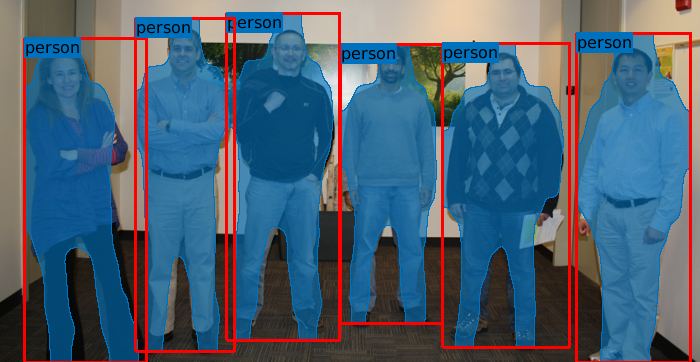

% Read the image for inference
img = imread('visionteam.jpg');

% Define the target size of the image for inference
targetSize = [700 700 3];

% Resize the image maintaining the aspect ratio and scaling the largest
% dimension to the target size.
imgSize = size(img);
[~, maxDim] = max(imgSize);
resizeSize = [NaN NaN];
resizeSize(maxDim) = targetSize(maxDim);

img = imresize(img, resizeSize);

% Setup network parameters
trainImgSize = [800 800 3];
classNames = {'person', 'car', 'Background'};
numClasses = 2;

% Create the network params structure
params = createMaskRCNNConfig(trainImgSize, numClasses, classNames);

% detect the objects and their masks
[boxes, scores, labels, masks] = detectMaskRCNN(net, maskSubnet, img, params, executionEnvironment);

%% Visualize Predictions

% Overlay the detected masks on the image using the insertObjectMask
% function.
if(isempty(masks))
    overlayedImage = img;
else
    overlayedImage = insertObjectMask(img, masks);
end
figure, imshow(overlayedImage)

% Show the bounding boxes and labels on the objects
showShape("rectangle", gather(boxes), "Label", labels, "LineColor",'r')